material = [10,50];
turn = [20, 40, 60];
f_ratio = [2,3,4];
ref_material = 50;
ref_turn = 20;
ref_f_ratio = 2;
voltage = [0 2.5, 3.5, 4.5, 5.5];
ref_ring = false;

## Material

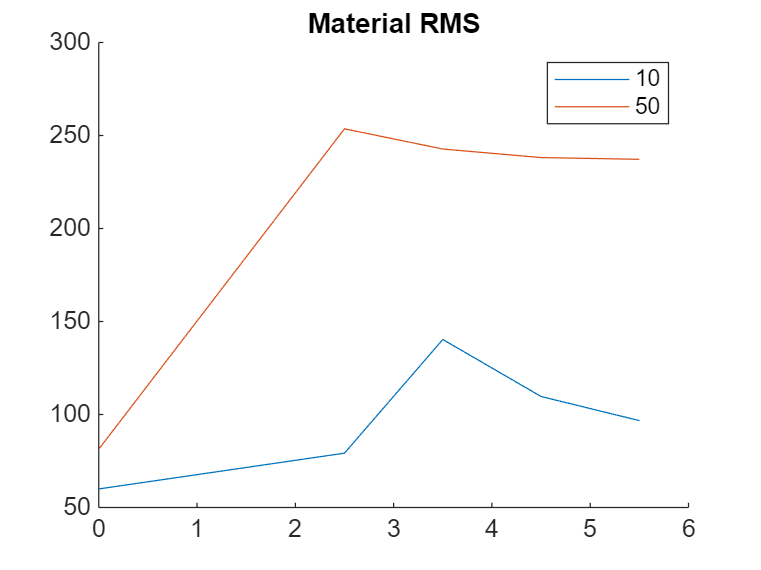

material_data = zeros(length(material),length(voltage),3);
for i = 1:length(material)
    sing_mat_data = zeros(length(voltage),3);
    for j = 1:length(voltage)
        [rms_data, magnitude] = single_coil_processing(material(i),ref_turn,ref_f_ratio,voltage(j),ref_ring);
        data2save = [voltage(j),rms_data,magnitude];
        sing_mat_data(j,:) = data2save;
    end
    material_data(i,:,:) = sing_mat_data;
end

figure('Name','Material RMS');
hold on
for i = 1:length(material)
    plot(material_data(i,:,1),material_data(i,:,2));
end
hold off
legend('10','50')
title('Material RMS')

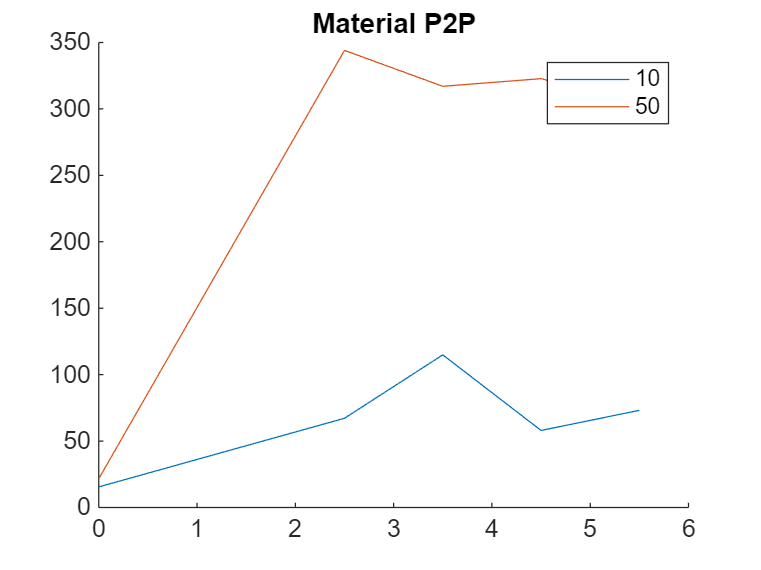


figure('Name','Material P2P');
hold on
for i = 1:length(material)
    plot(material_data(i,:,1),material_data(i,:,3));
end
hold off
legend('10','50')
title('Material P2P')

## Turn

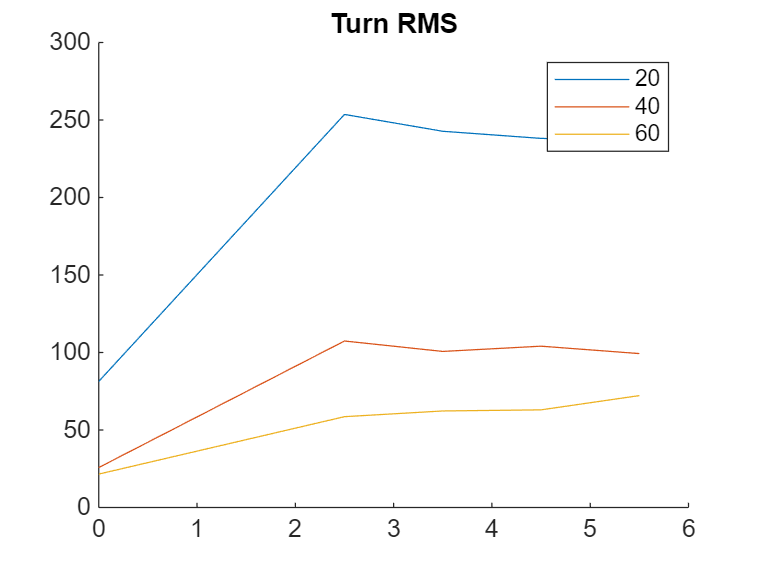

turn_data = zeros(length(turn),length(voltage),3);
for i = 1:length(turn)
    sing_turn_data = zeros(length(voltage),3);
    for j = 1:length(voltage)
        [rms_data, magnitude] = single_coil_processing(ref_material,turn(i),ref_f_ratio,voltage(j),ref_ring);
        data2save = [voltage(j),rms_data,magnitude];
        sing_turn_data(j,:) = data2save;
    end
    turn_data(i,:,:) = sing_turn_data;
end

figure('Name','Turn RMS');
hold on
for i = 1:3
    plot(turn_data(i,:,1),turn_data(i,:,2));
end
hold off
legend('20','40','60')
title('Turn RMS')

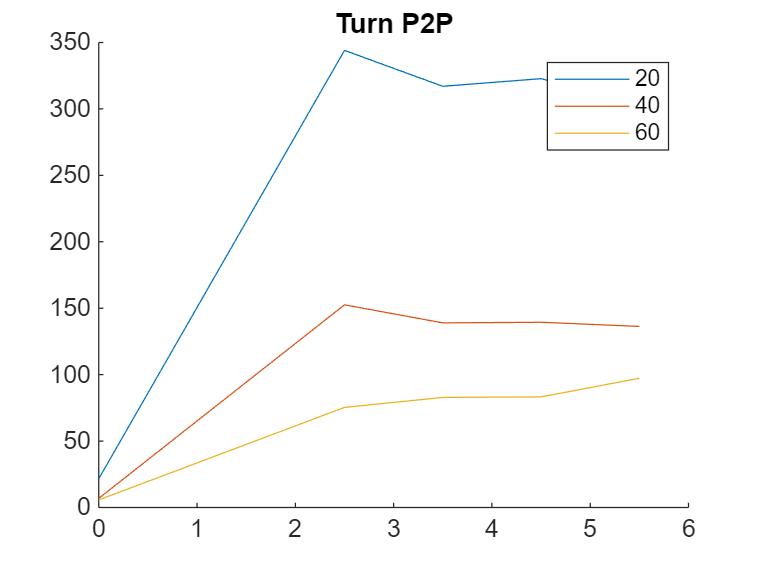


figure('Name','Turn P2P');
hold on
for i = 1:3
    plot(turn_data(i,:,1),turn_data(i,:,3));
end
hold off
legend('20','40','60')
title('Turn P2P')

## Ferrite ratio

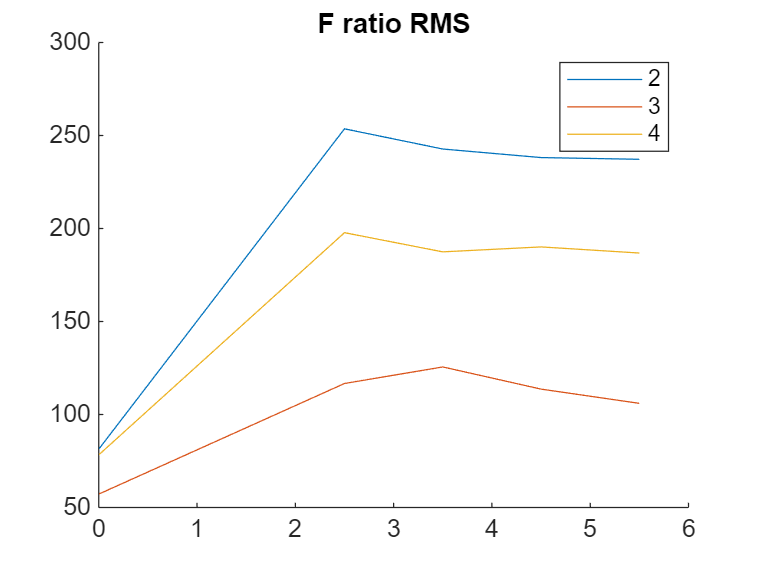

fratio_data = zeros(length(f_ratio),length(voltage),3);
for i = 1:length(f_ratio)
    sing_fratio_data = zeros(length(voltage),3);
    for j = 1:length(voltage)
        [rms_data, magnitude] = single_coil_processing(ref_material,ref_turn,f_ratio(i),voltage(j),ref_ring);
        data2save = [voltage(j),rms_data,magnitude];
        sing_fratio_data(j,:) = data2save;
    end
    fratio_data(i,:,:) = sing_fratio_data;
end

figure('Name','F ratio RMS');
hold on
for i = 1:3
    plot(fratio_data(i,:,1),fratio_data(i,:,2));
end
hold off
legend('2','3','4')
title('F ratio RMS')

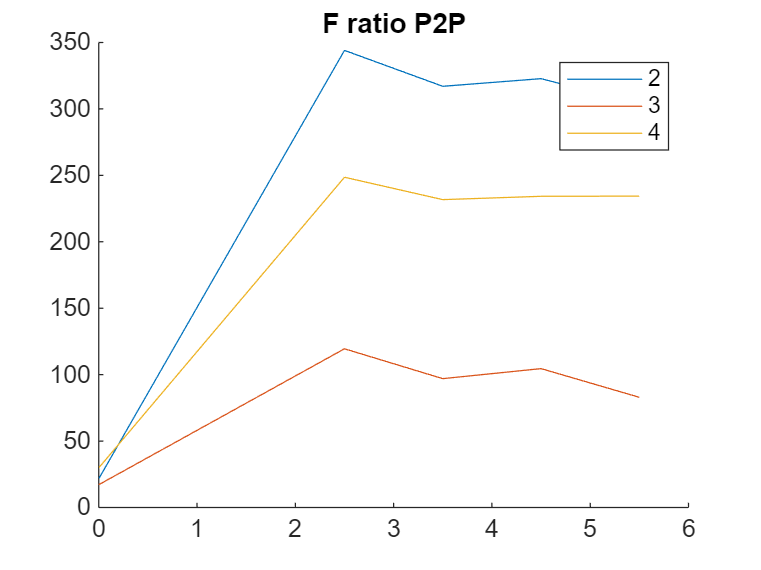


figure('Name','F ratio P2P');
hold on
for i = 1:3
    plot(fratio_data(i,:,1),fratio_data(i,:,3));
end
hold off
legend('2','3','4')
title('F ratio P2P')

## Outside ring

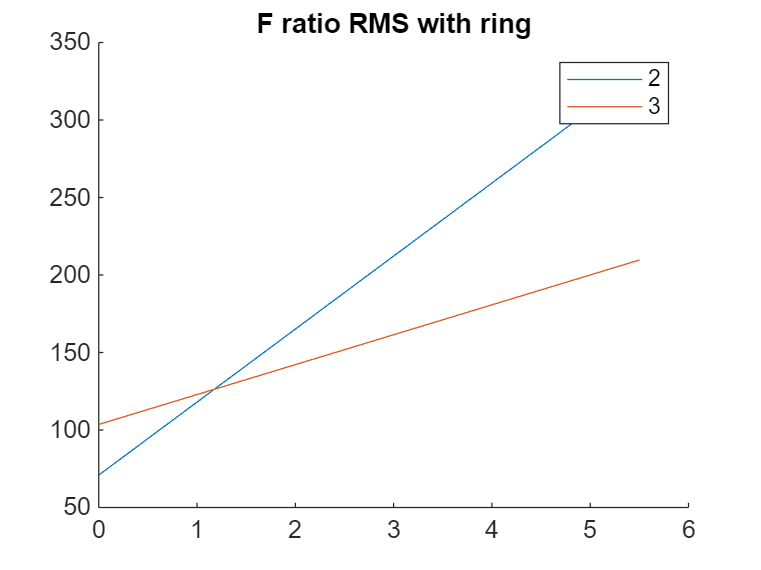

ring_voltage = [0, 5.5];
ring_f_ratio = [2,3];
ring = true;

ring_data = zeros(length(ring_f_ratio),length(ring_voltage),3);
for i = 1:length(ring_f_ratio)
    sing_ring_data = zeros(length(ring_voltage),3);
    for j = 1:length(ring_voltage)
        [rms_data, magnitude] = single_coil_processing(ref_material,ref_turn,ring_f_ratio(i),ring_voltage(j),ring);
        data2save = [ring_voltage(j),rms_data,magnitude];
        sing_ring_data(j,:) = data2save;
    end
    ring_data(i,:,:) = sing_ring_data;
end

figure('Name','F ratio RMS');
hold on
for i = 1:length(ring_f_ratio)
    plot(ring_data(i,:,1),ring_data(i,:,2));
end
hold off
legend('2','3')
title('F ratio RMS with ring')

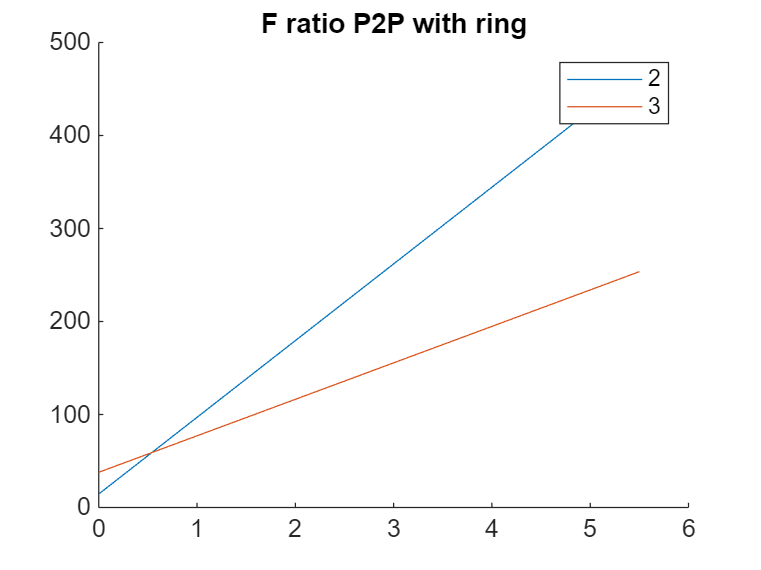


figure('Name','F ratio P2P');
hold on
for i = 1:length(ring_f_ratio)
    plot(ring_data(i,:,1),ring_data(i,:,3));
end
hold off
legend('2','3')
title('F ratio P2P with ring')